# XTD_C2: w/in vs xEpoch Interval Decoding vs Chance

% fileDirs = [{'D:\PFC\GE11_Session132'},...
%     {'D:\PFC\GE13_Session083'},...
%     {'D:\PFC\GE14_Session123'},...
%     {'D:\PFC\GE17_Session095'},...
%     {'D:\PFC\GE24_Session096'}];
fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);
nanWmap = rbDivMap;
nanWmap(1,:) = [1,1,1];

## Compile Data Across Rats

prevTrlLat = cell(1,4);
trialLightLat = cell(1,4);
pokeInLat = cell(1,4);
rwdSigLat = cell(1,4);
pokeOutLat = cell(1,4);
rwdLat = cell(1,4);
nxtTrlLat = cell(1,4);
for ani = 1:length(fileDirs)
    aniDta = load([fileDirs{ani} '\xtd_mlb_wChance.mat'], 'xInt_prePreInt_Real', 'xInt_pstPstInt_Real', 'xInt_prePstInt_Real', 'xInt_pstPreInt_Real',...
        'xInt_prePreInt_ChanceFull', 'xInt_pstPstInt_ChanceFull', 'xInt_prePstInt_ChanceFull', 'xInt_pstPreInt_ChanceFull',...
        'xInt_prePreInt_ChancePos', 'xInt_pstPstInt_ChancePos', 'xInt_prePstInt_ChancePos', 'xInt_pstPreInt_ChancePos');
fns = fieldnames(aniDta);
    if ani == 1
        for fn = 1:length(fns)
            eval(sprintf('%s = aniDta.%s;', fns{fn}, fns{fn}));
        end
    else
        for d = 1:numel(xInt_prePreInt_Real)
            for fn = 1:length(fns)
                eval(sprintf('%s{d} = cat(3,%s{d}, aniDta.%s{d});', fns{fn}, fns{fn}, fns{fn}));
            end
        end
    end
    load([fileDirs{ani} '\xtd_mlb_wChance.mat'], 'trialInfo', 'mlb');
    cur_TrialInfo = cell2mat(trialInfo(cellfun(@(a)~isempty(a),trialInfo))');
    for pos = 1:mlb.seqLength
        curPosLog = [cur_TrialInfo.Position]==pos;
        if strcmp(mlb.alignments{1}, 'PokeIn')
            prevTrlLat{pos} = [prevTrlLat{pos},([cur_TrialInfo(curPosLog).PrevTrlEnd] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            trialLightLat{pos} = [trialLightLat{pos}, ([cur_TrialInfo(curPosLog).PortLightIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            pokeInLat{pos} = [pokeInLat{pos},([cur_TrialInfo(curPosLog).PokeInIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            rwdSigLat{pos} = [rwdSigLat{pos}, ([cur_TrialInfo(curPosLog).RewardSignalIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            pokeOutLat{pos} = [pokeOutLat{pos}, [cur_TrialInfo(curPosLog).PokeDuration]];
            rwdLat{pos} = [rwdLat{pos}, ([cur_TrialInfo(curPosLog).RewardIndex] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
            nxtTrlLat{pos} = [nxtTrlLat{pos}, ([cur_TrialInfo(curPosLog).NextTrlStart] - [cur_TrialInfo(curPosLog).PokeInIndex])/mlb.sampleRate];
        elseif strcmp(mlb.alignmnents{1}, 'PokeOut')
            prevTrlLat{pos} = [prevTrlLat{pos},([cur_TrialInfo(curPosLog).PrevTrlEnd] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            trialLightLat{pos} = [trialLightLat{pos}, ([cur_TrialInfo(curPosLog).PortLightIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            pokeInLat{pos} = [pokeOutLat{pos}, [cur_TrialInfo(curPosLog).PokeDuration]*-1];
            rwdSigLat{pos} = [rwdSigLat{pos}, ([cur_TrialInfo(curPosLog).RewardSignalIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            pokeOutLat{pos} = [pokeInLat{pos},([cur_TrialInfo(curPosLog).PokeOutIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            rwdLat{pos} = [rwdLat{pos}, ([cur_TrialInfo(curPosLog).RewardIndex] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
            nxtTrlLat{pos} = [nxtTrlLat{pos}, ([cur_TrialInfo(curPosLog).NextTrlStart] - [cur_TrialInfo(curPosLog).PokeOutIndex])/mlb.sampleRate];
        end
    end
end


## Plot Things

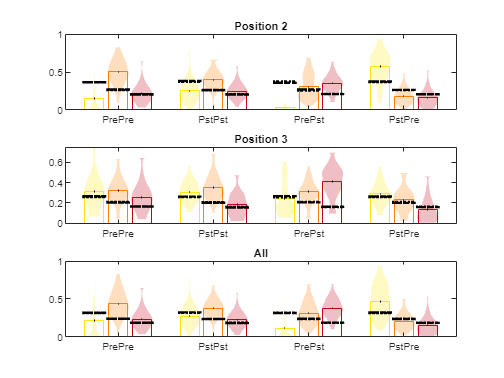

figure; 
allPrePre_RealPrev = cell(1,mlb.seqLength-2);
allPrePre_Real = cell(1,mlb.seqLength-2);
allPrePre_RealNext = cell(1,mlb.seqLength-2);
allPrePre_ChancePrev = nan(2,mlb.seqLength-2);
allPrePre_Chance = nan(2,mlb.seqLength-2);
allPrePre_ChanceNext = nan(2,mlb.seqLength-2);

allPstPst_RealPrev = cell(1,mlb.seqLength-2);
allPstPst_Real = cell(1,mlb.seqLength-2);
allPstPst_RealNext = cell(1,mlb.seqLength-2);
allPstPst_ChancePrev = nan(2,mlb.seqLength-2);
allPstPst_Chance = nan(2,mlb.seqLength-2);
allPstPst_ChanceNext = nan(2,mlb.seqLength-2);

allPrePst_RealPrev = cell(1,mlb.seqLength-2);
allPrePst_Real = cell(1,mlb.seqLength-2);
allPrePst_RealNext = cell(1,mlb.seqLength-2);
allPrePst_ChancePrev = nan(2,mlb.seqLength-2);
allPrePst_Chance = nan(2,mlb.seqLength-2);
allPrePst_ChanceNext = nan(2,mlb.seqLength-2);

allPstPre_RealPrev = cell(1,mlb.seqLength-2);
allPstPre_Real = cell(1,mlb.seqLength-2);
allPstPre_RealNext = cell(1,mlb.seqLength-2);
allPstPre_ChancePrev = nan(2,mlb.seqLength-2);
allPstPre_Chance = nan(2,mlb.seqLength-2);
allPstPre_ChanceNext = nan(2,mlb.seqLength-2);
for trlPos = 2:mlb.seqLength-1
    tempPrePre_RealPrev = nan(1,size(xInt_prePreInt_Real{trlPos,trlPos,trlPos,trlPos-1},3));
    tempPrePre_Real = nan(1,size(xInt_prePreInt_Real{trlPos,trlPos,trlPos,trlPos},3));
    tempPrePre_RealNext = nan(1,size(xInt_prePreInt_Real{trlPos,trlPos,trlPos,trlPos+1},3));
    tempPrePre_ChancePrev = [mean(xInt_prePreInt_ChanceFull{trlPos,trlPos,trlPos,trlPos-1},'all','omitnan'), mean(xInt_prePreInt_ChancePos{trlPos,trlPos,trlPos,trlPos-1},'all','omitnan')];
    tempPrePre_Chance = [mean(xInt_prePreInt_ChanceFull{trlPos,trlPos,trlPos,trlPos},'all','omitnan'), mean(xInt_prePreInt_ChancePos{trlPos,trlPos,trlPos,trlPos},'all','omitnan')];
    tempPrePre_ChanceNext = [mean(xInt_prePreInt_ChanceFull{trlPos,trlPos,trlPos,trlPos+1},'all','omitnan'), mean(xInt_prePreInt_ChancePos{trlPos,trlPos,trlPos,trlPos+1},'all','omitnan')];

    tempPstPst_RealPrev = nan(1,size(xInt_pstPstInt_Real{trlPos,trlPos,trlPos,trlPos-1},3));
    tempPstPst_Real = nan(1,size(xInt_pstPstInt_Real{trlPos,trlPos,trlPos,trlPos},3));
    tempPstPst_RealNext = nan(1,size(xInt_pstPstInt_Real{trlPos,trlPos,trlPos,trlPos+1},3));
    tempPstPst_ChancePrev = [mean(xInt_pstPstInt_ChanceFull{trlPos,trlPos,trlPos,trlPos-1},'all','omitnan'), mean(xInt_pstPstInt_ChancePos{trlPos,trlPos,trlPos,trlPos-1},'all','omitnan')];
    tempPstPst_Chance = [mean(xInt_pstPstInt_ChanceFull{trlPos,trlPos,trlPos,trlPos},'all','omitnan'), mean(xInt_pstPstInt_ChancePos{trlPos,trlPos,trlPos,trlPos},'all','omitnan')];
    tempPstPst_ChanceNext = [mean(xInt_pstPstInt_ChanceFull{trlPos,trlPos,trlPos,trlPos+1},'all','omitnan'), mean(xInt_pstPstInt_ChancePos{trlPos,trlPos,trlPos,trlPos+1},'all','omitnan')];
    
    tempPrePst_RealPrev = nan(1,size(xInt_prePstInt_Real{trlPos,trlPos,trlPos,trlPos-1},3));
    tempPrePst_Real = nan(1,size(xInt_prePstInt_Real{trlPos,trlPos,trlPos,trlPos},3));
    tempPrePst_RealNext = nan(1,size(xInt_prePstInt_Real{trlPos,trlPos,trlPos,trlPos+1},3));
    tempPrePst_ChancePrev = [mean(xInt_prePstInt_ChanceFull{trlPos,trlPos,trlPos,trlPos-1},'all','omitnan'), mean(xInt_prePstInt_ChancePos{trlPos,trlPos,trlPos,trlPos-1},'all','omitnan')];
    tempPrePst_Chance = [mean(xInt_prePstInt_ChanceFull{trlPos,trlPos,trlPos,trlPos},'all','omitnan'), mean(xInt_prePstInt_ChancePos{trlPos,trlPos,trlPos,trlPos},'all','omitnan')];
    tempPrePst_ChanceNext = [mean(xInt_prePstInt_ChanceFull{trlPos,trlPos,trlPos,trlPos+1},'all','omitnan'), mean(xInt_prePstInt_ChancePos{trlPos,trlPos,trlPos,trlPos+1},'all','omitnan')];
    
    tempPstPre_RealPrev = nan(1,size(xInt_pstPreInt_Real{trlPos,trlPos,trlPos,trlPos-1},3));
    tempPstPre_Real = nan(1,size(xInt_pstPreInt_Real{trlPos,trlPos,trlPos,trlPos},3));
    tempPstPre_RealNext = nan(1,size(xInt_pstPreInt_Real{trlPos,trlPos,trlPos,trlPos+1},3));
    tempPstPre_ChancePrev = [mean(xInt_pstPreInt_ChanceFull{trlPos,trlPos,trlPos,trlPos-1},'all','omitnan'), mean(xInt_pstPreInt_ChancePos{trlPos,trlPos,trlPos,trlPos-1},'all','omitnan')];
    tempPstPre_Chance = [mean(xInt_pstPreInt_ChanceFull{trlPos,trlPos,trlPos,trlPos},'all','omitnan'), mean(xInt_pstPreInt_ChancePos{trlPos,trlPos,trlPos,trlPos},'all','omitnan')];
    tempPstPre_ChanceNext = [mean(xInt_pstPreInt_ChanceFull{trlPos,trlPos,trlPos,trlPos+1},'all','omitnan'), mean(xInt_pstPreInt_ChancePos{trlPos,trlPos,trlPos,trlPos+1},'all','omitnan')];
    for t = 1:length(tempPrePre_Real)
        tempPrePre_RealPrev(t) = mean(xInt_prePreInt_Real{trlPos,trlPos,trlPos,trlPos-1}(:,:,t),'all','omitnan');
        tempPrePre_Real(t) = mean(xInt_prePreInt_Real{trlPos,trlPos,trlPos,trlPos}(:,:,t),'all','omitnan');
        tempPrePre_RealNext(t) = mean(xInt_prePreInt_Real{trlPos,trlPos,trlPos,trlPos+1}(:,:,t),'all','omitnan');

        tempPstPst_RealPrev(t) = mean(xInt_pstPstInt_Real{trlPos,trlPos,trlPos,trlPos-1}(:,:,t),'all','omitnan');
        tempPstPst_Real(t) = mean(xInt_pstPstInt_Real{trlPos,trlPos,trlPos,trlPos}(:,:,t),'all','omitnan');
        tempPstPst_RealNext(t) = mean(xInt_pstPstInt_Real{trlPos,trlPos,trlPos,trlPos+1}(:,:,t),'all','omitnan');

        tempPrePst_RealPrev(t) = mean(xInt_prePstInt_Real{trlPos,trlPos,trlPos,trlPos-1}(:,:,t),'all','omitnan');
        tempPrePst_Real(t) = mean(xInt_prePstInt_Real{trlPos,trlPos,trlPos,trlPos}(:,:,t),'all','omitnan');
        tempPrePst_RealNext(t) = mean(xInt_prePstInt_Real{trlPos,trlPos,trlPos,trlPos+1}(:,:,t),'all','omitnan');

        tempPstPre_RealPrev(t) = mean(xInt_pstPreInt_Real{trlPos,trlPos,trlPos,trlPos-1}(:,:,t),'all','omitnan');
        tempPstPre_Real(t) = mean(xInt_pstPreInt_Real{trlPos,trlPos,trlPos,trlPos}(:,:,t),'all','omitnan');
        tempPstPre_RealNext(t) = mean(xInt_pstPreInt_Real{trlPos,trlPos,trlPos,trlPos+1}(:,:,t),'all','omitnan');
    end
    allPrePre_RealPrev{trlPos-1} = tempPrePre_RealPrev;
    allPrePre_Real{trlPos-1} = tempPrePre_Real;
    allPrePre_RealNext{trlPos-1} = tempPrePre_RealNext;
    allPrePre_ChancePrev(:,trlPos-1) = tempPrePre_ChancePrev';
    allPrePre_Chance(:,trlPos-1) = tempPrePre_Chance';
    allPrePre_ChanceNext(:,trlPos-1) = tempPrePre_ChanceNext';

    allPstPst_RealPrev{trlPos-1} = tempPstPst_RealPrev;
    allPstPst_Real{trlPos-1} = tempPstPst_Real;
    allPstPst_RealNext{trlPos-1} = tempPstPst_RealNext;
    allPstPst_ChancePrev(:,trlPos-1) = tempPstPst_ChancePrev';
    allPstPst_Chance(:,trlPos-1) = tempPstPst_Chance';
    allPstPst_ChanceNext(:,trlPos-1) = tempPstPst_ChanceNext';
    
    allPrePst_RealPrev{trlPos-1} = tempPrePst_RealPrev;
    allPrePst_Real{trlPos-1} = tempPrePst_Real;
    allPrePst_RealNext{trlPos-1} = tempPrePst_RealNext;
    allPrePst_ChancePrev(:,trlPos-1) = tempPrePst_ChancePrev';
    allPrePst_Chance(:,trlPos-1) = tempPrePst_Chance';
    allPrePst_ChanceNext(:,trlPos-1) = tempPrePst_ChanceNext';
    
    allPstPre_RealPrev{trlPos-1} = tempPstPre_RealPrev;
    allPstPre_Real{trlPos-1} = tempPstPre_Real;
    allPstPre_RealNext{trlPos-1} = tempPstPre_RealNext;
    allPstPre_ChancePrev(:,trlPos-1) = tempPstPre_ChancePrev';
    allPstPre_Chance(:,trlPos-1) = tempPstPre_Chance';
    allPstPre_ChanceNext(:,trlPos-1) = tempPstPre_ChanceNext';    

    subplot(mlb.seqLength-1,1,trlPos-1);
    pres1 = 2;
    pres2 = 6;
    pres3 = 10;
    pres4 = 14;
    mlb.PlotMeanVarViolin(pres1-1,tempPrePre_RealPrev,2,0.05,mlb.PPFcolors(1,:));
    plot(pres1+[-1.5,-0.5], repmat(tempPrePre_ChancePrev(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres1+[-1.5,-0.5], repmat(tempPrePre_ChancePrev(2),[1,2]), '-.k', 'linewidth', 2);
    mlb.PlotMeanVarViolin(pres1,tempPrePre_Real,2,0.05,mlb.PPFcolors(2,:));
    plot(pres1+[-0.5,0.5], repmat(tempPrePre_Chance(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres1+[-0.5,0.5], repmat(tempPrePre_Chance(2),[1,2]), '-.k', 'linewidth', 2);
    mlb.PlotMeanVarViolin(pres1+1,tempPrePre_RealNext,2,0.05,mlb.PPFcolors(3,:));
    plot(pres1+[0.5,1.5], repmat(tempPrePre_ChanceNext(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres1+[0.5,1.5], repmat(tempPrePre_ChanceNext(2),[1,2]), '-.k', 'linewidth', 2);

    mlb.PlotMeanVarViolin(pres2-1,tempPstPst_RealPrev,2,0.05,mlb.PPFcolors(1,:));
    plot(pres2+[-1.5,-0.5], repmat(tempPstPst_ChancePrev(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres2+[-1.5,-0.5], repmat(tempPstPst_ChancePrev(2),[1,2]), '-.k', 'linewidth', 2);
    mlb.PlotMeanVarViolin(pres2,tempPstPst_Real,2,0.05,mlb.PPFcolors(2,:));
    plot(pres2+[-0.5,0.5], repmat(tempPstPst_Chance(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres2+[-0.5,0.5], repmat(tempPstPst_Chance(2),[1,2]), '-.k', 'linewidth', 2);
    mlb.PlotMeanVarViolin(pres2+1,tempPstPst_RealNext,2,0.05,mlb.PPFcolors(3,:));
    plot(pres2+[0.5,1.5], repmat(tempPstPst_ChanceNext(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres2+[0.5,1.5], repmat(tempPstPst_ChanceNext(2),[1,2]), '-.k', 'linewidth', 2);
    
    mlb.PlotMeanVarViolin(pres3-1,tempPrePst_RealPrev,2,0.05,mlb.PPFcolors(1,:));
    plot(pres3+[-1.5,-0.5], repmat(tempPrePst_ChancePrev(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres3+[-1.5,-0.5], repmat(tempPrePst_ChancePrev(2),[1,2]), '-.k', 'linewidth', 2);
    mlb.PlotMeanVarViolin(pres3,tempPrePst_Real,2,0.05,mlb.PPFcolors(2,:));
    plot(pres3+[-0.5,0.5], repmat(tempPrePst_Chance(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres3+[-0.5,0.5], repmat(tempPrePst_Chance(2),[1,2]), '-.k', 'linewidth', 2);
    mlb.PlotMeanVarViolin(pres3+1,tempPrePst_RealNext,2,0.05,mlb.PPFcolors(3,:));
    plot(pres3+[0.5,1.5], repmat(tempPrePst_ChanceNext(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres3+[0.5,1.5], repmat(tempPrePst_ChanceNext(2),[1,2]), '-.k', 'linewidth', 2);
    
    mlb.PlotMeanVarViolin(pres4-1,tempPstPre_RealPrev,2,0.05,mlb.PPFcolors(1,:));
    plot(pres4+[-1.5,-0.5], repmat(tempPstPre_ChancePrev(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres4+[-1.5,-0.5], repmat(tempPstPre_ChancePrev(2),[1,2]), '-.k', 'linewidth', 2);
    mlb.PlotMeanVarViolin(pres4,tempPstPre_Real,2,0.05,mlb.PPFcolors(2,:));
    plot(pres4+[-0.5,0.5], repmat(tempPstPre_Chance(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres4+[-0.5,0.5], repmat(tempPstPre_Chance(2),[1,2]), '-.k', 'linewidth', 2);
    mlb.PlotMeanVarViolin(pres4+1,tempPstPre_RealNext,2,0.05,mlb.PPFcolors(3,:));
    plot(pres4+[0.5,1.5], repmat(tempPstPre_ChanceNext(1),[1,2]), ':k', 'linewidth', 2);
    plot(pres4+[0.5,1.5], repmat(tempPstPre_ChanceNext(2),[1,2]), '-.k', 'linewidth', 2);


    set(gca,'xtick', [pres1,pres2,pres3,pres4], 'xticklabels', [{'PrePre'}, {'PstPst'}, {'PrePst'}, {'PstPre'}]);
    title(sprintf('Position %i',trlPos));
end

subplot(mlb.seqLength-1,1,mlb.seqLength-1);
pres1 = 2;
pres2 = 6;
pres3 = 10;
pres4 = 14;
mlb.PlotMeanVarViolin(pres1-1,cell2mat(allPrePre_RealPrev),2,0.05,mlb.PPFcolors(1,:));
plot(pres1+[-1.5,-0.5], repmat(mean(allPrePre_ChancePrev(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres1+[-1.5,-0.5], repmat(mean(allPrePre_ChancePrev(2,:)),[1,2]), '-.k', 'linewidth', 2);
mlb.PlotMeanVarViolin(pres1,cell2mat(allPrePre_Real),2,0.05,mlb.PPFcolors(2,:));
plot(pres1+[-0.5,0.5], repmat(mean(allPrePre_Chance(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres1+[-0.5,0.5], repmat(mean(allPrePre_Chance(2,:)),[1,2]), '-.k', 'linewidth', 2);
mlb.PlotMeanVarViolin(pres1+1,cell2mat(allPrePre_RealNext),2,0.05,mlb.PPFcolors(3,:));
plot(pres1+[0.5,1.5], repmat(mean(allPrePre_ChanceNext(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres1+[0.5,1.5], repmat(mean(allPrePre_ChanceNext(2,:)),[1,2]), '-.k', 'linewidth', 2);

mlb.PlotMeanVarViolin(pres2-1,cell2mat(allPstPst_RealPrev),2,0.05,mlb.PPFcolors(1,:));
plot(pres2+[-1.5,-0.5], repmat(mean(allPstPst_ChancePrev(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres2+[-1.5,-0.5], repmat(mean(allPstPst_ChancePrev(2,:)),[1,2]), '-.k', 'linewidth', 2);
mlb.PlotMeanVarViolin(pres2,cell2mat(allPstPst_Real),2,0.05,mlb.PPFcolors(2,:));
plot(pres2+[-0.5,0.5], repmat(mean(allPstPst_Chance(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres2+[-0.5,0.5], repmat(mean(allPstPst_Chance(2,:)),[1,2]), '-.k', 'linewidth', 2);
mlb.PlotMeanVarViolin(pres2+1,cell2mat(allPstPst_RealNext),2,0.05,mlb.PPFcolors(3,:));
plot(pres2+[0.5,1.5], repmat(mean(allPstPst_ChanceNext(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres2+[0.5,1.5], repmat(mean(allPstPst_ChanceNext(2,:)),[1,2]), '-.k', 'linewidth', 2);

mlb.PlotMeanVarViolin(pres3-1,cell2mat(allPrePst_RealPrev),2,0.05,mlb.PPFcolors(1,:));
plot(pres3+[-1.5,-0.5], repmat(mean(allPrePst_ChancePrev(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres3+[-1.5,-0.5], repmat(mean(allPrePst_ChancePrev(2,:)),[1,2]), '-.k', 'linewidth', 2);
mlb.PlotMeanVarViolin(pres3,cell2mat(allPrePst_Real),2,0.05,mlb.PPFcolors(2,:));
plot(pres3+[-0.5,0.5], repmat(mean(allPrePst_Chance(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres3+[-0.5,0.5], repmat(mean(allPrePst_Chance(2,:)),[1,2]), '-.k', 'linewidth', 2);
mlb.PlotMeanVarViolin(pres3+1,cell2mat(allPrePst_RealNext),2,0.05,mlb.PPFcolors(3,:));
plot(pres3+[0.5,1.5], repmat(mean(allPrePst_ChanceNext(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres3+[0.5,1.5], repmat(mean(allPrePst_ChanceNext(2,:)),[1,2]), '-.k', 'linewidth', 2);

mlb.PlotMeanVarViolin(pres4-1,cell2mat(allPstPre_RealPrev),2,0.05,mlb.PPFcolors(1,:));
plot(pres4+[-1.5,-0.5], repmat(mean(allPstPre_ChancePrev(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres4+[-1.5,-0.5], repmat(mean(allPstPre_ChancePrev(2,:)),[1,2]), '-.k', 'linewidth', 2);
mlb.PlotMeanVarViolin(pres4,cell2mat(allPstPre_Real),2,0.05,mlb.PPFcolors(2,:));
plot(pres4+[-0.5,0.5], repmat(mean(allPstPre_Chance(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres4+[-0.5,0.5], repmat(mean(allPstPre_Chance(2,:)),[1,2]), '-.k', 'linewidth', 2);
mlb.PlotMeanVarViolin(pres4+1,cell2mat(allPstPre_RealNext),2,0.05,mlb.PPFcolors(3,:));
plot(pres4+[0.5,1.5], repmat(mean(allPstPre_ChanceNext(1,:)),[1,2]), ':k', 'linewidth', 2);
plot(pres4+[0.5,1.5], repmat(mean(allPstPre_ChanceNext(2,:)),[1,2]), '-.k', 'linewidth', 2);


set(gca,'xtick', [pres1,pres2,pres3,pres4], 'xticklabels', [{'PrePre'}, {'PstPst'}, {'PrePst'}, {'PstPre'}]);
title('All');

## Stats: Prove that index changes across the trial period.

1) Decodings by epoch...

    --- PrePre vs PrePst: ** Looks Ahead **

        --- Decreased decoding of past... 

        --- Decreased/NSD decoding present...

        --- Increased decoding of future...

    --- PstPst vs PstPre: ** Looks Backward **

        --- Opposite dynamic

2) Matched decoding by trials... matched decodings vs chance

3) 